# 25 Introduction to the Various Connectivity Analyses

Neural networks operate at multiple spatial and temporal scales, and considerable empirical research from multiple species, theories, and mathematical models over the past several decades points to oscillatory synchronization as being a key mechanism by which neural populations transmit information and form larger networks.

The term "connectivity" is used here to refer to any analysis for which more than one signal is considered at a time. This mostly refers to two signals from two different electrodes but can also refer to two signals from the same electrode or multiple signals from multiple electrodes. The term connectivity includes measures based on phase and on power using a variety of linear and nonlinear methods. These analyses often have disparate assumptions and utilize different aspects of the EEG signal but share the common goal of identifying brain connectivity; thus, the term connectivity is used to refer generally to all analyses that share this goal.

## 25.1 Why Only Two Sites (Bivariate Connectivity)?

Most but not all brain connectivity measures are bivariate, meaning that they involve interactions between only two brain regions/electrodes. Some brain connectivity measures may initially seem multivariate (one-to-all or all-to-all connectivity) but are in fact mass-bivariate measures because each step of the analysis involves connectivity between only a pair of electrodes.

Why are most connectivity measures bivariate? 

- There are few detailed models of multinode networks that are widely used in cognitive electrophysiology.

- Increasingly complex models of multinode brain interactions become increasingly difficult to conceptualize, and thus, it is easier to break them down into a set of simpler bivariate cases.

- The brain really works that way, and bivariate connections are the most relevant types of connections for many cognitive functions.

You should be aware that bivariate correlations can inflate or misrepresent estimates of relationships if the network structure is actually multivariate. This is particularly relevant for brain connectivity because the brain is a highly multivariate system. For task-related connectivity this potential inflation is mitigated somewhat by condition comparisons because inflated connectivity estimates should affect all conditions, and therefore, the inflation should subtract out during condition comparisons of connectivity.

## 25.2 Important Concepts Related to Bivariate Connectivity

The following four points should be kept in mind when you are interpreting results of bivariate connectivity analyses:

- For many (though not all) types of connectivity analyses, the phase lag between the two electrodes is not taken into consideration. What matters is that the phase lag is consistent across time and/or trials.

- A nonzero phase lag in connectivity does not necessarily imply a causal or directed relationship. Nonzero connectivity lag can be considered supporting evidence consistent with a causal or directed relationship, but this should be interpreted cautiously.

- Fhase-based and power-based measures of connectivity tend to reveal different patterns of results. This is not surprising from a mathematical perspective because phase and power are mostly independent measures.

- Many connectivity results can be confounded by volume conduction.

Some measures such as Granger prediction and the phase-slope-index provide better evidence for directed connectivity compared to connectivity measures based on phase angle distributions or power correlations. Nonetheless, because the brain is an enormously complex and dynamic system, because it is not possible to record from all components of this system at the same time, and because data contain noise, it is difficult to determine unambiguously whether a pattern of bivariate connectivity is truly causal.

A distinction can be made between functional and effective connectivity:

- Functional connectivity refers to linear or nonlinear covariation between fluctuations in activity recorded from distinct neural networks.

- Effective connectivity refers to a causal influence of activity in one neural network over activity in another neural network.

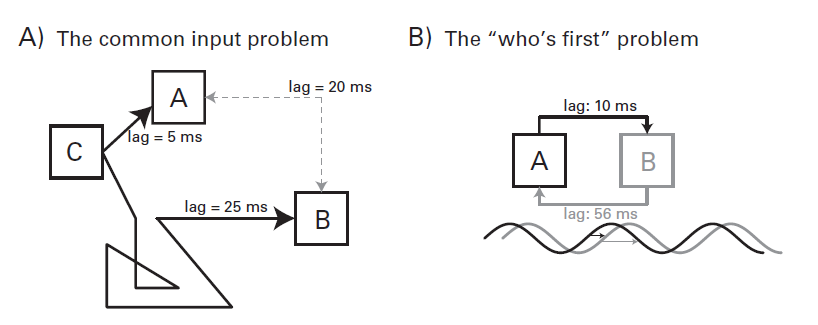

**Figure 25.1**

*Two scenarios to keep in mind when interpreting temporally lagged bivariate connectivity results.*

## 25.3 Which Measure of Connectivity Should Be Used?

There are several classes of bivariate connectivity analyses (e.g., phase based vs. power based), several different analyses within each class, and several parameters and analysis options of each analysis. Each analysis has its advantages and limitations, and different measures are better suited for different purposes or assumptions about underlying neurocognitive processes.

There is no correct or best connectivity method. Even when simulated data with known connectivity patterns are used, there may be no clear "winner" method that outperforms all other methods in all situations: 

- Some methods are more amenable to hypothesis testing, whereas others are more amenable to exploratory analyses. 

- Some methods have a clear neurophysiological interpretation, whereas others are more based on computer science and engineering principles. 

- Some methods are established and widely used, and other methods are novel and more open to development and validation.

## 25.4 Phase-Based Connectivity

Phase-based connectivity analyses rely on the distribution of phase angle differences between two electrodes, with the idea that when neural populations are functionally coupled, the timing of their oscillatory processes, as measured through phase, becomes synchronized. The mathematics of phase-based connectivity analyses is similar to that underlying ITPC.

There are several advantages to phase-based connectivity analyses: 

- Are widely used in many experiments and across many species.

- Have been used to examine network formation and network dynamics on many spatial and temporal scales. 

- Have a neurophysiological interpretation. 

- Are computationally fast, and thus, the results can be inspected quickly.

- The analyses require few assumptions or parameter selections other than the parameters already selected for the time-frequency decomposition. 

- Some phase-based analyses are also insensitive to time lag (others are sensitive to lag).

There are also a few disadvantages: 

- Rely on precise temporal relationships, usually in the identical frequency band, and are therefore susceptible to temporal jitter or uncertainty in the precise timing of experiment events. 

- Do not provide compelling evidence for directionality.

## 25.5 Power-Based Connectivity

Power-based connectivity analyses involve correlating time-frequency power between two electrodes across time or over trials. These correlations can be computed between activity in the same or different frequencies and at the same or different time points.

Power-based connectivity measures provide ample opportunities for flexible analyses that can be custom-tailored toward testing specific hypotheses, and they can also be used for data-driven exploratory analyses. Power-based connectivity measures are arguably the most similar to connectivity measures often used in fMRI, because the correlated fluctuations in activity are relatively slower, compared to phase-based connectivity measures. Power-based connectivity measures are also relatively insensitive to temporal jitter and uncertainty.

## 25.6 Granger Prediction

Granger prediction (also called Granger causality) tests whether variance in one signal can be predicted from variance in another signal earlier in time. Granger prediction is similar to, and in some cases identical to, other autoregression-based estimates of directed connectivity, including the directed transfer function and partial directed coherence.

The main advantages of Granger prediction are that it tests for and can dissociate directional connectivity. It can ignore simultaneous connectivity, which makes it less susceptible to volume conduction. There are several sophisticated analyses of multivariate networks that are based on Granger prediction, although usually in the literature (and in this book), the "basic" bivariate Granger prediction analyses are applied.

There are a few disadvantages of Granger prediction: 

- Is sensitive to violations of stationarity.

- Can be computationally time-consuming to perform.

- Doubles the number of results because each pair of electrodes contains two connectivity values.

## 25.7 Mutual Information

Mutual information is a simple but robust method of detecting shared information between two variables. It is computed based on the distributions of values within variables and the joint distribution of two (or more) variables.

There are several advantages of mutual information analyses: 

- Can detect many kinds of relationships, including linear and nonlinear interactions that a correlation would fail to identify. 

- Has a long tradition of use and development in engineering and information technology. 

- There are also several extensions for using mutual information and entropy to estimate system complexity or signal transmission integrity (e.g., channel-coding theorem).

There are also a few disadvantages of using mutual information for examining brain connectivity: 

- Does not provide information as to whether a relationship is linear or nonlinear, or positive or negative. 

- Is sensitive to the number of histogram bins. This is easy to control for but could be a significant confound if not addressed during analyses. 

- Can be computationally intensive, particularly if used for exploratory analyses. 

- Although it is a widely used signal-processing technique and may be particularly advantageous for quantifying nonlinear interactions, it does not have a clear neurophysiological interpretation.

## 25.8 Cross-Frequency Coupling

Cross-frequency coupling refers to a statistical relationship between activities in two different frequency bands. It can be used to infer: 

- Local organization (when measured at a single electrode).

- Long-range connectivity (when activity from the two frequency bands is measured from different electrodes). 

There are several advantages of cross-frequency coupling: 

- It provides findings that can be linked across species and to computational models.

- There are theories proposing a key role of cross-frequency coupling in information processing in the brain. 

- It might also help identify task-related high-frequency power, which may be difficult to identify with EEG in trial-averaging-based analyses).

The main disadvantage is that there is a potentially huge search space (frequencies $\times$ frequencies $\times$ electrodes $\times$ electrodes $\times$ conditions $\times$ time), which means that cross-frequency coupling analyses can be time-consuming and that there are many tests to control for during statistical evaluation. These can be minimized if you have hypotheses to help constrain the analyses.

## 25.9 Graph Theory

Graph theory is a mathematical framework for characterizing networks that can be represented as graphs containing nodes and vertices (for EEG connectivity, nodes and vertices are, respectively, electrodes and connectivity strengths). There are many analyses that fall under the umbrella term graph theory, and they are generally useful for providing summary information regarding large-scale or multivariate network dynamics.

There are several advantages of graph-theory-based analyses: 

- They provide useful and often easy-to-interpret characterizations of multivariate networks. 

- They can facilitate cross-methods and cross-species comparisons.

- There are arguably an underutilized analysis framework in cognitive electrophysiology that may provide novel insights into the electrophysiological network-level mechanisms of cognitive processes.

The main disadvantage of graph-theory-based measures is that they are often (although not always) used in exploratory data-mining analyses that lack a theoretical framework within which to understand the findings and link the results to other known functional properties of the brain. The reason this can be a disadvantage is that there are many graph-theory-based metrics that are used and relatively few applications, and it can be difficult to compare findings across studies that use different methods and that do not test specific hypotheses.

## 25.10 Potential Confound of Volume Conduction

Volume conduction is a potential confound that can lead to spurious connectivity results. There are two related concerns: 

- Sources in the brain generate large electromagnetic fields that are measured by more than one EEG electrode or MEG sensor, thus introducing spatial autocorrelation at the electrode level.

- Electrical fields spread "laterally" through head tissues (skull, skin, etc.) and thus spread to neighboring electrodes. This problem affects EEG only; magnetic fields pass through these tissues undisturbed.

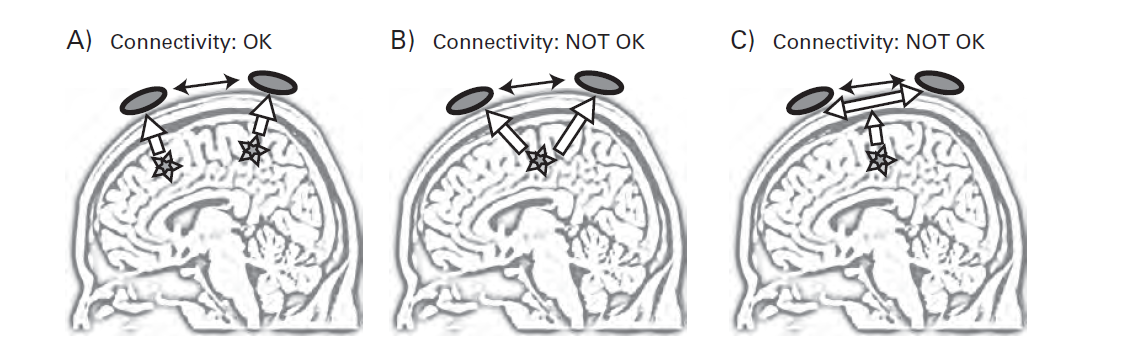

**Figure 25.2**

*Illustration of the danger of volume conduction for interpreting interelectrode connectivity results.*

There are several options for addressing these potential confounds for connectivity analyses. No single option is optimal in all situations; instead, how you address this confound depends on the type of analysis performed and on the experimental design. It also depends on how hypothesis-driven versus exploratory your analyses are: 

- In hypothesis-driven analyses you might want to use analysis methods that have maximal sensitivity to detect true brain connectivity and then examine each effect for potential confounds.

- In exploratory analyses you might want to use methods that are insensitive to volume conduction even though those methods may have decreased sensitivity to detect true brain connectivity.

If your connectivity finding is an artifact of volume conduction, you can expect the following pattern of results:

- Zero or $\pi$ phase lag Because volume-conducted activity is recorded instantaneously at multiple electrodes.

- Very strong connectivity at neighboring electrodes and a decrease of connectivity strength with increasing interelectrode distance.

- Positive correlations In the frequency and time-frequency domains.

- Positive correlations between connectivity and power in the same frequency band.

There are at least 10 approaches to addressing the potential contamination of volume conduction:

- Apply a spatial filter prior to computing connectivity, such as the surface Laplacian or source imaging.

- Examine only negative correlations in the frequency or time-frequency domains.

- Test for temporally lagged connectivity rather than zero-phase connectivity.

- Test for condition differences in connectivity rather than single-condition effects.

- Test for a cross-frequency correlation.

- Test for a statistical or qualitative dissociation between connectivity and power.

- Test whether the phase lag of connectivity between electrodes is significantly different from zero or $\pi$.

- For phase-based connectivity, you can use measures that are insensitive to volume conduction.

- For power-based connectivity, you can compute partial correlations between two electrodes holding constant a third electrode.

- For power-based connectivity you can modify pairs of time series before calculating connectivity such that the coherent real parts (which include volume conduction effects) are removed, thereby removing any potentially volume-conducted signals.

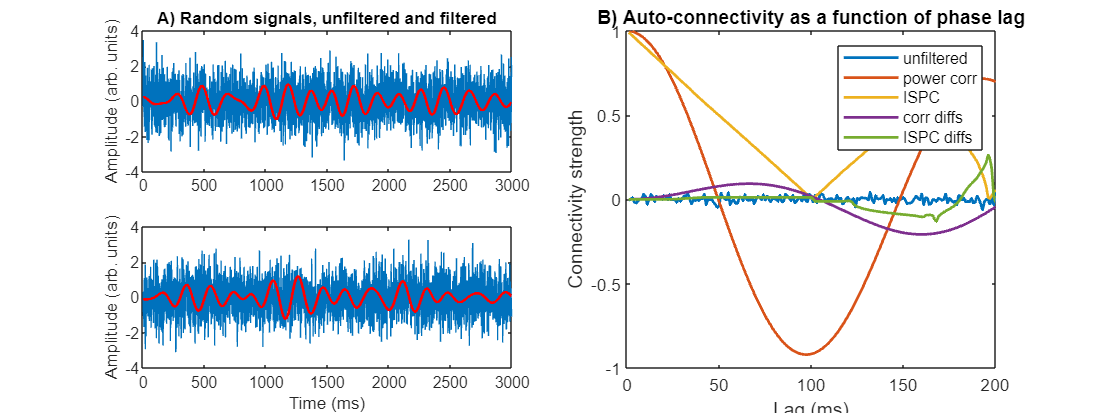

srate = 1000;
randsig1 = randn(1, 3*srate);
randsig2 = randn(1, 3*srate);

f       = 5;
time    = -1:1/srate:1;
s       = 6/(2*pi*f);
wavelet = exp(2*pi*1i*f.*time) .* exp(-time.^2./(2*s^2));

n_wavelet            = length(wavelet);
n_data               = length(randsig1);
n_convolution        = n_wavelet + n_data - 1;
half_of_wavelet_size = (length(wavelet) - 1)/2;

convolution_result_fft = ifft(fft(wavelet, n_convolution) .* fft(randsig1, n_convolution), n_convolution) * sqrt(s)/10;
filtsig1  = real(convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size));
anglesig1 = angle(convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size));

convolution_result_fft = ifft(fft(wavelet, n_convolution) .* fft(randsig2, n_convolution), n_convolution) * sqrt(s)/10;
filtsig2  = real(convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size));
anglesig2 = angle(convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size));

correlations = zeros(5, round(1000/f));

for i = 1:round(1000/f)
    temp = corrcoef(randsig1(1:end-i), randsig1(i+1:end));
    correlations(1, i) = temp(1, 2);
    
    temp = corrcoef(filtsig1(1:end-i), filtsig1(i+1:end));
    correlations(2, i) = temp(1, 2);
    
    correlations(3, i) = abs(mean(exp(1i * angle(anglesig1(1:end-i) - anglesig1(i+1:end)))));
    
    temp = corrcoef(filtsig2(1:end-i), filtsig2(i+1:end));
    correlations(4, i) = temp(1, 2) - correlations(2, i);
    
    correlations(5, i) = abs(mean(exp(1i * angle(anglesig2(1:end-i) - anglesig2(i+1:end))))) - correlations(3, i);
end

figure(Position=[100, 100, 800, 300])

subplot(2, 2, 1)
plot(randsig1)
hold on
plot(filtsig1, 'r', 'LineWidth', 1.5)
ylabel('Amplitude (arb. units)')
title('A) Random signals, unfiltered and filtered')

subplot(2, 2, 3)
plot(randsig2)
hold on
plot(filtsig2, 'r', 'LineWidth', 1.5)
xlabel('Time (ms)')
ylabel('Amplitude (arb. units)')

subplot(2, 2, [2 4])
plot(correlations', 'LineWidth', 1.5)
xlabel('Lag (ms)')
ylabel('Connectivity strength')
title('B) Auto-connectivity as a function of phase lag')
legend({'unfiltered'; 'power corr'; 'ISPC'; 'corr diffs'; 'ISPC diffs'})

**Figure 25.3**

*Illustration of how autocorrelation can be induced from bandpass filtering and how condition subtractions can attenuate the autocorrelation inflations.*